# Sample 4-5

## 線形シフト不変システム

畳み込み行列

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Linear shift-invariant systems

Convolution matrix

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 単変量畳み込み

(Univariate convolution)

有限インパルス応答(FIR)$\{h[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{h}}\subset\mathbb{Z}}$を有する線形シフト不変システム $T(\cdot)$を仮定する．(Let us assume a linear shift-invariant system $T(\cdot)$ with a finite impulse response (FIR) $\{h[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{h}}\subset\mathbb{Z}}$.)

 $T(\cdot)$ の配列 $\{u[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{u}}\subset\mathbb{Z}}$に対する応答 $\{v[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{u}}\subset\mathbb{Z}}$は畳み込み (The response  $\{v[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{u}}\subset\mathbb{Z}}$ to the array  $\{u[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{u}}\subset\mathbb{Z}}$ of  $T(\cdot)$  can be represented by convolution 

        
$$\{v[n]\}_n =T\left(\{u[n]\}_n\right) = \sum_{k\in\Omega_\mathrm{h}}h[k]\{u\left[n-k\right]\}_n.$$


により表現できる．

#### 信号の生成

(Signal generation)

% Generating an input sequence u[n] of finite support region
Q = 6; 
ugen = "(1:Q)";
u = eval(ugen)

u =      1     2     3     4     5     6


#### インパルス応答の設定

(Setting the impulse response)

% Setting the shift amount 
h = [1 0 -1];

#### 写像の定義

(Definition of a map)

% Definition of map T as a convolution with h[n]
mapT = @(x) conv(x,h);

#### 写像の結果

(Result of mapping)

% Mapping with the circular shift T(.)
v = mapT(u)

v =      1     2     2     2     2     2    -5    -6


### 単変量畳み込みの行列表現

(Matrix representation of the univariate convolution)

FIRシステムの畳み込み演算は (The convolution of an FIR system can be represented as a matrix as)

        
$$\mathbf{v}=\mathbf{Tu},$$


のように行列表現できる． 

インパルス応答 $\{h[n]\}_n$ のサポート領域が $\Omega_\mathrm{h}=\{0,1,2\}$，入力信号$\{u[n]\}_n$のサポート領域が$\Omega_\mathrm{u}=\{0,1,2,3,4,5\}$ のとき，出力信号$\{v[n]\}_n$のサポート領域は$\Omega_\mathrm{v}=\{0,1,2,3,4,5,6,7\}$となり，(When the support region of the impulse response  $\{h[n]\}_n$ is $\Omega_\mathrm{h}=\{0,1,2\}$ and the support region of the input signal $\{u[n]\}_n$ is $\Omega_\mathrm{u}=\{0,1,2,3,4,5\}$, the support region of the output signal $\{v[n]\}_n$ is $\Omega_\mathrm{v}=\{0,1,2,3,4,5,6,7\}$ and can be expressed as)

       
$$\mathbf{v}=\mathrm{vec}\left(\{v[{n}]\}_{n}\right)=\left(\begin{array}{c}v[0]\\v[1]\\v[2]\\v[3]\\v[4]\\v[5]\\v[6]\\v[7]\end{array}\right), \mathbf{u}=\mathrm{vec}\left(\{u[{n}]\}_{n}\right)=\left(\begin{array}{c}u[0]\\u[1]\\u[2]\\u[3]\\u[4]\\u[5]\end{array}\right)$$


        
$$\mathbf{T}
=\left(\begin{array}{cccccc}
h[0] & 0  & 0 & 0 & 0 & 0 \\
h[1] & h[0]  & 0 & 0 & 0 & 0 \\
h[2] & h[1]  & h[0] & 0 & 0 & 0 \\
0 & h[2] & h[1]  & h[0] & 0 & 0 \\
0 & 0 & h[2] & h[1]  & h[0] & 0 \\
0 & 0 & 0 & h[2] & h[1]  & h[0]  \\
0 & 0 & 0 & 0 & h[2]  & h[1]  \\
0 & 0 & 0 & 0 & 0  & h[2] 
\end{array}\right).$$


と表現できる．なお，出力のサポート領域が$\Omega_\mathrm{v}=\{(n+k)\in\mathbb{Z}|n\in\Omega_\mathrm{u},k\in\Omega_\mathrm{h}\}$となり $\mathbf{T}$ の行数が (Note that the support area of the output is $\Omega_\mathrm{v}=\{(n+k)\in\mathbb{Z}|n\in\Omega_\mathrm{u},k\in\Omega_\mathrm{h}\}$ and the number of rows in $\mathbf{T}$  is 

        
$$|\Omega_\mathrm{v}|=|\Omega_\mathrm{u}|+|\Omega_\mathrm{h}|-1=6+3-1=8.$$


となることに注意する．

#### 単変量畳み込みの行列生成

(Matrix generation of univariate convolution)

% Find the matrix representation of the univariate convolution
T = zeros(length(u)+length(h)-1,length(u));
for idx = 1:length(u)
    % Generating a standard basis vector
    e = zeros(size(u),'like',u);
    e(idx) = 1;
    % Response to the standard basis vector
    T(:,idx) = mapT(e); 
end
% Matrix representation of the univariate convolution
T

T =      1     0     0     0     0     0
     0     1     0     0     0     0
    -1     0     1     0     0     0
     0    -1     0     1     0     0
     0     0    -1     0     1     0
     0     0     0    -1     0     1
     0     0     0     0    -1     0
     0     0     0     0     0    -1


#### 関数CONVMTXの利用

(Using the CONVMTX function)

単変量畳み込み行列の生成に関数CONVMTXも利用できる．

(The function CONVMTX can also be used to generate univariate convolutional matrices.)

% Generating the matrix representation of the univariate convolution by CONVMTX
H = convmtx(h(:),length(u)) %#ok

H =      1     0     0     0     0     0
     0     1     0     0     0     0
    -1     0     1     0     0     0
     0    -1     0     1     0     0
     0     0    -1     0     1     0
     0     0     0    -1     0     1
     0     0     0     0    -1     0
     0     0     0     0     0    -1


### 行列演算による単変量畳み込み

(Univariate convolution by matrix operation)

畳み込みは可換図に沿って (Convolution can be computed as)

    
$$\{v[{n}]\}_{n}=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\left(\mathbf{v}\right)=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\left(\mathbf{Tu}\right)=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\circ\mathbf{T}\mathrm{vec}_{\Omega_\mathrm{u}}\left(\{u[n]\}_n\right)$$


のように行列演算が可能である．すなわち，(along the commutative diagram. That is, we have)

        
$$T=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\circ\mathbf{T}\mathrm{vec}_{\Omega_\mathrm{u}}.$$


と表現できる．

% Column vectorization of sequence u[n]
vecu = u(:);

% Matrix operation
vecv = T*vecu;

% Reshaping the result into the row sequnece
recv = reshape(vecv,[1 (length(u)+length(h)-1)])

recv =      1     2     2     2     2     2    -5    -6


#### 行列演算による単変量畳み込みの評価

(Evaluation of univariate convolution by matrix operation)

% Comparizon between mapping and matrix operation
mse(v,recv)

ans = 0

### 2変量畳み込み

(Bivariate convolution)

2変量の有限インパルス応答(FIR)$\{h[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in{\Omega_\mathrm{h}}\subset\mathbb{Z}^2}$を有する線形シフト不変システム $T(\cdot)$を仮定する．( (Assume a linear shift-invariant system T with a bivariate finite impulse response (FIR) $\{h[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in{\Omega_\mathrm{h}}\subset\mathbb{Z}^2}$.)  

 $T(\cdot)$ の配列 $\{u[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in{\Omega_\mathrm{u}}\subset\mathbb{Z}^2}$に対する応答 $\{v[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in{\Omega_\mathrm{u}}\subset\mathbb{Z}^2}$は畳み込み (The response $\{v[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in{\Omega_\mathrm{u}}\subset\mathbb{Z}^2}$ to the array $\{u[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in{\Omega_\mathrm{u}}\subset\mathbb{Z}^2}$ of $T(\cdot)$  can be represented by convolution )

        
$$\{v[\mathbf{n}
]\}_\mathbf{n} =T\left(\{u[\mathbf{n}]\}_\mathbf{n}\right) = \sum_{k\in\Omega_\mathrm{h}}h[\mathbf{k}]\{u\left[\mathbf{n}-\mathbf{k}\right]\}_\mathbf{n}.$$


により表現できる．

#### 信号の生成

(Signal generation)

% Generating an input array u[n1,n2] of finite support region
N1 = 2; % # of rows
N2 = 3; % # of columns
ugen = "reshape((0:N1*N2-1),[N1 N2])";
u = eval(ugen)

u =      0     2     4
     1     3     5


#### インパルス応答の設定

(Setting the impulse response)

h = [1 -1 ; 1 -1]

h =      1    -1
     1    -1


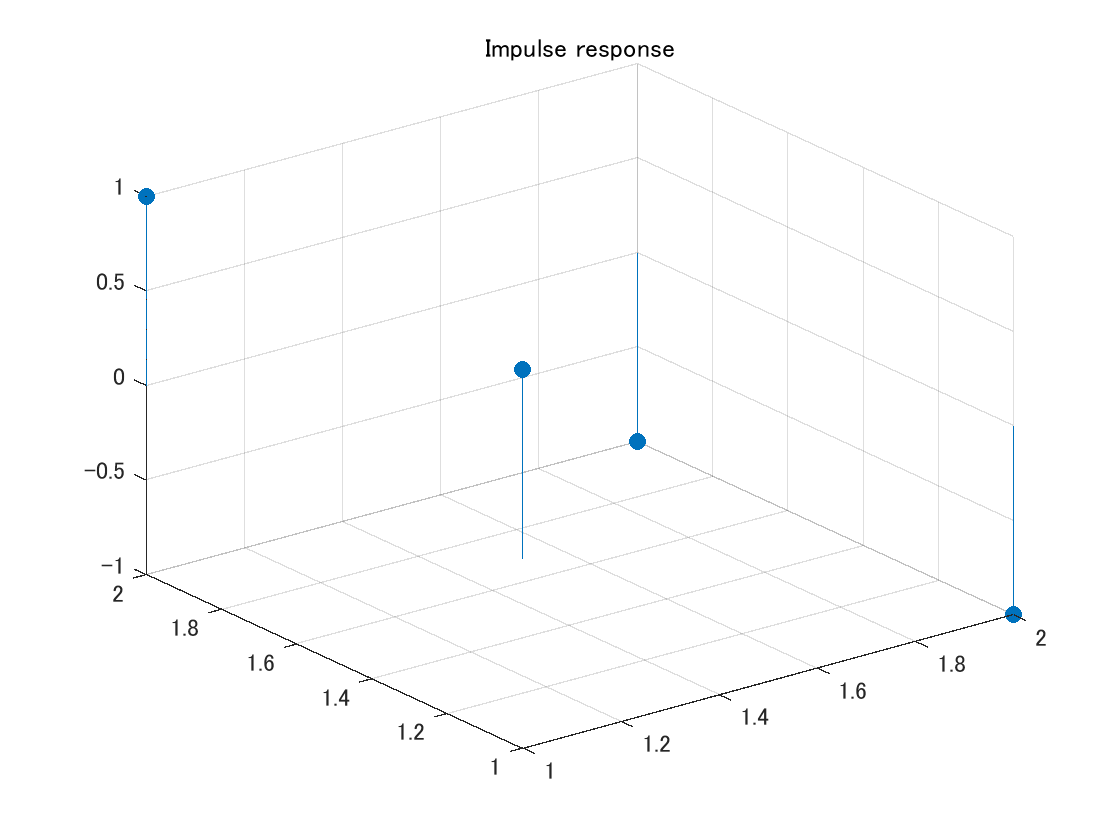

figure(1)
stem3(h,'filled')
title('Impulse response')

#### 写像の定義

(Definition of a map)

% Definition of map T as a convolution with h[n]
mapT = @(x) imfilter(x,h,'conv','full'); % or conv2(x,h);

#### 写像の結果

(Result of mapping)

% Mapping with the circular shift T(.)
v = mapT(u)

v =      0     2     2    -4
     1     4     4    -9
     1     2     2    -5


### 2変量畳み込みの行列表現

(Matrix representation of the bivariate convolution)

2変量FIRシステムの畳み込み演算は (The convolution of a bivariate FIR system can be represented as a matrix as)

        
$$\mathbf{v}=\mathbf{Tu},$$


のように行列表現できる． 

インパルス応答 $\{h[\mathbf{n}]\}_\mathbf{n}$ のサポート領域が $\Omega_\mathrm{h}=\{0,1\}\times \{0,1\}$，入力信号$\{u[\mathbf{n}]\}_\mathbf{n}$のサポート領域が$\Omega_\mathrm{u}=\{0,1\}\times \{0,1,2\}$ のとき，出力信号$\{v[\mathbf{n}]\}_\mathbf{n}$のサポート領域は$\Omega_\mathrm{v}=\{0,1,2\}\times\{0,1,2,3\}$となり，(If the support region  of the impulse response $\{h[\mathbf{n}]\}_\mathbf{n}$  is  $\Omega_\mathrm{h}=\{0,1\}\times \{0,1\}$, and the support region of the input signal $\{u[\mathbf{n}]\}_\mathbf{n}$ is $\Omega_\mathrm{u}=\{0,1\}\times \{0,1,2\}$, then the support region of the output signal $\{v[\mathbf{n}]\}_\mathbf{n}$ is $\Omega_\mathrm{v}=\{0,1,2\}\times\{0,1,2,3\}$ and can be expressed as )

     
$$\mathbf{v}=\mathrm{vec}\left(\{v[\mathbf{n}]\}_\mathbf{n}\right)=\left(\begin{array}{c}
v[0,0]\\v[1,0]\\v[2,0]\\v[0,1]\\\vdots\\v[2,3]\end{array}\right), \mathbf{u}=\mathrm{vec}\left(\{u[\mathbf{n}]\}_\mathbf{n}\right)=\left(\begin{array}{c}u[0,0]\\u[1,0]\\u[0,1]\\u[1,1]\\\vdots\\u[1,2]\end{array}\right)$$


        
$$\mathbf{T}
=\left(\begin{array}{cccccc}
h[0,0] &  0 & 0 & 0 & \cdots & 0 \\
h[1,0]  & h[0,0]  & 0 & 0 & \cdots & 0 \\
0 & h[1,0]  & h[0,0] & 0 & \cdots & 0 \\
h[1,0]  & 0 & h[1,0]  & h[0,0] & \cdots & 0 \\
h[1,1]  & h[1,0] & 0 & h[1,0]  & \cdots & 0 \\
0 & h[1,1] & h[1,0] & 0 & \cdots & 0  \\
\vdots & \vdots & \vdots & \vdots & \ddots  & \vdots  \\
0 & 0 & 0 & 0 & \cdots  & h[1,1] 
\end{array}\right).$$


と表現できる．なお，出力のサポート領域が$\Omega_\mathrm{v}=\{(n+k)\in\mathbb{Z}|n\in\Omega_\mathrm{u},k\in\Omega_\mathrm{h}\}$となり $\mathbf{T}$ の行数が (Note that the support region of the output is $\Omega_\mathrm{v}=\{(n+k)\in\mathbb{Z}|n\in\Omega_\mathrm{u},k\in\Omega_\mathrm{h}\}$ and the number of rows in $\mathbf{T}$is )

    
$$|\Omega_\mathrm{v}|=(2+2-1)\times(3+2-1)=2\times 4=12.$$


となることに注意する．

#### 2変量畳み込みの行列生成

(Matrix generation of bivariate matrix)

% Find the matrix representation of the convolution
T = zeros(prod(size(u)+size(h)-1),numel(u));
for idx = 1:numel(u)
    % Generating a standard basis vector
    e = zeros(size(u),'like',u);
    e(idx) = 1;
    % Response to the standard basis vector
    T(:,idx) = reshape(mapT(e),[size(T,1) 1]); 
end
% Matrix representation of the convolution
T

T =      1     0     0     0     0     0
     1     1     0     0     0     0
     0     1     0     0     0     0
    -1     0     1     0     0     0
    -1    -1     1     1     0     0
     0    -1     0     1     0     0
     0     0    -1     0     1     0
     0     0    -1    -1     1     1
     0     0     0    -1     0     1
     0     0     0     0    -1     0


#### 関数CONVMTX2の利用

(Using the CONVMTX2 function)

2変量畳み込み行列の生成に関数CONVMTX2も利用できる．

(The function CONVMTX2 can also be used to generate bivariate convolutional matrices.)

% Generating the matrix representation of the bivariate convolution by CONVMTX2
H = convmtx2(h,size(u)) %#ok

H =    (1,1)        1
   (2,1)        1
   (4,1)       -1
   (5,1)       -1
   (2,2)        1
   (3,2)        1
   (5,2)       -1
   (6,2)       -1
   (4,3)        1
   (5,3)        1
   (7,3)       -1
   (8,3)       -1
   (5,4)        1
   (6,4)        1
   (8,4)       -1
   (9,4)       -1
   (7,5)        1
   (8,5)        1
  (10,5)       -1
  (11,5)       -1
   (8,6)        1
   (9,6)        1
  (11,6)       -1
  (12,6)       -1


### 行列演算による2変量畳み込み

(Bivariate convolution by matrix operation)

畳み込みは可換図に沿って (Convolution can be computed as)

    
$$\{v[{n}]\}_{n}=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\left(\mathbf{v}\right)=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\left(\mathbf{Tu}\right)=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\circ\mathbf{T}\mathrm{vec}_{\Omega_\mathrm{u}}\left(\{u[n]\}_n\right)$$


のように行列演算が可能である．すなわち，(along the commutative diagram. That is, we have)

        
$$T=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\circ\mathbf{T}\mathrm{vec}_{\Omega_\mathrm{u}}.$$


と表現できる．

% Column vectorization of sequence u[n]
vecu = u(:);

% Matrix operation
vecv = T*vecu;

% Reshaping the result into the row sequnece
recv = reshape(vecv,(size(u)+size(h)-1))

recv =      0     2     2    -4
     1     4     4    -9
     1     2     2    -5


#### 行列演算による単変量畳み込みの評価

(Evaluation of univariate convolution by matrix operation)

% Comparizon between mapping and matrix operation
mse(v,recv)

ans = 0

© Copyright, Shogo MURAMATSU, All rights reserved.